Constants for FFT

Fs = 1 / 0.001;

cd("C:\DavidZaha\Programming\Vanderbilt\sysphys\headphone-eeg-comparison\filtered_data")

files = dir('*.csv');

% Initialize a structure array to store results
EEG_Analyzed_Data = struct();



for i = 1:length(files)
    filename = files(i).name;
    
  
    
    [~, name, ~] = fileparts(filename);
    parts = split(name, '_');            
    subject = parts{1};
    experiment = parts{2};
    
    data = readtable(filename);
    
    
    time = data{:, 1};       
    electrode1 = data{:, 2}; 
    electrode2 = data{:, 3};  
    electrode3 = data{:, 4};  
    electrode4 = data{:, 5};  
    
    Y1 = fft(electrode1);
    Y2 = fft(electrode2);
    Y3 = fft(electrode3);
    Y4 = fft(electrode4);
    
    EEG_Analyzed_Data.(subject).(experiment).right_parietal = abs(Y1(1:floor(N/2)));
    EEG_Analyzed_Data.(subject).(experiment).central = abs(Y2(1:floor(N/2)));
    EEG_Analyzed_Data.(subject).(experiment).right_frontal = abs(Y3(1:floor(N/2)));
    EEG_Analyzed_Data.(subject).(experiment).left_temporal = abs(Y4(1:floor(N/2)));

    
end




% accessing data from the struct
% EEG_Analyzed_Data.s01.ex05.right_frontal

disp(EEG_Analyzed_Data.s01)


Plotting accross electrodes for one subject and experiment

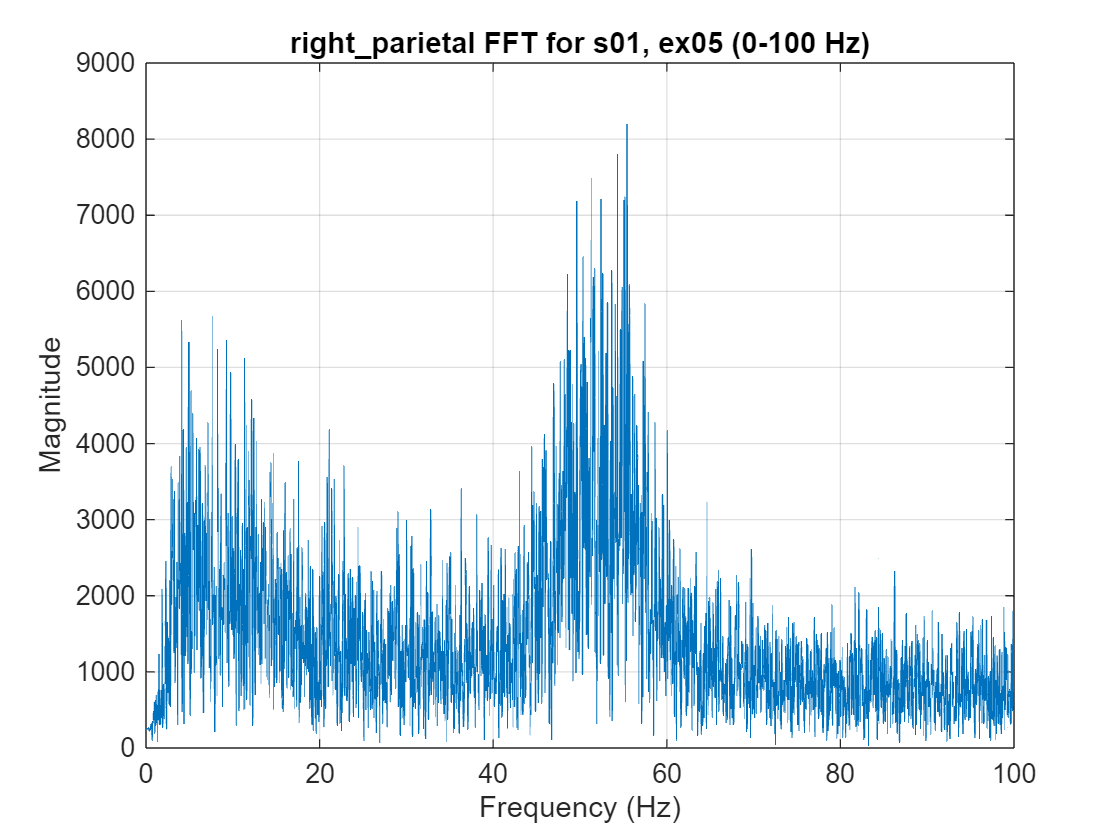

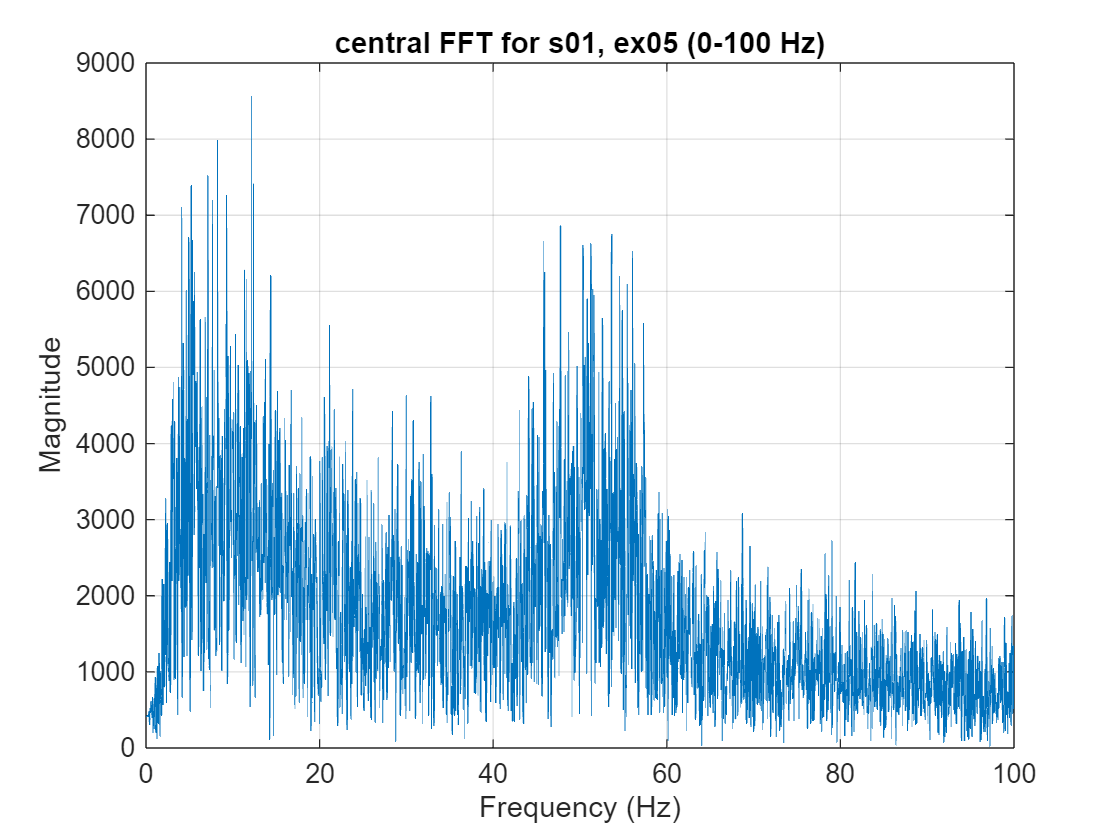

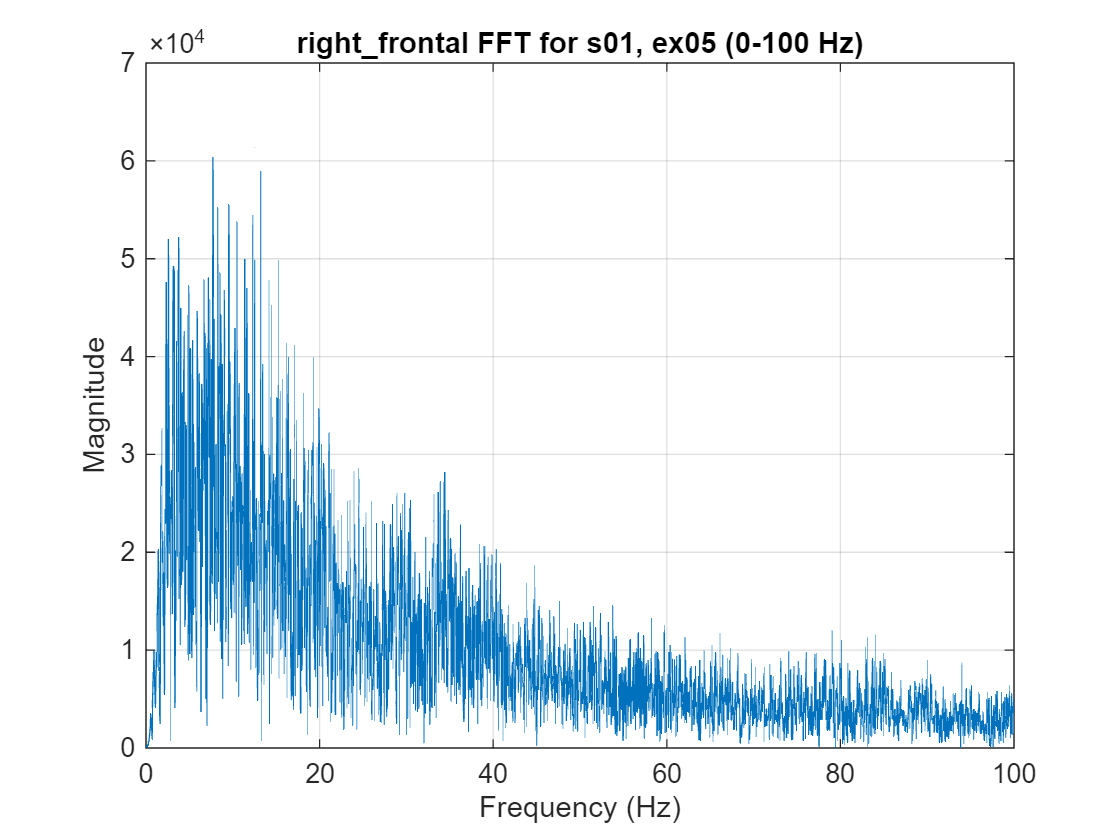

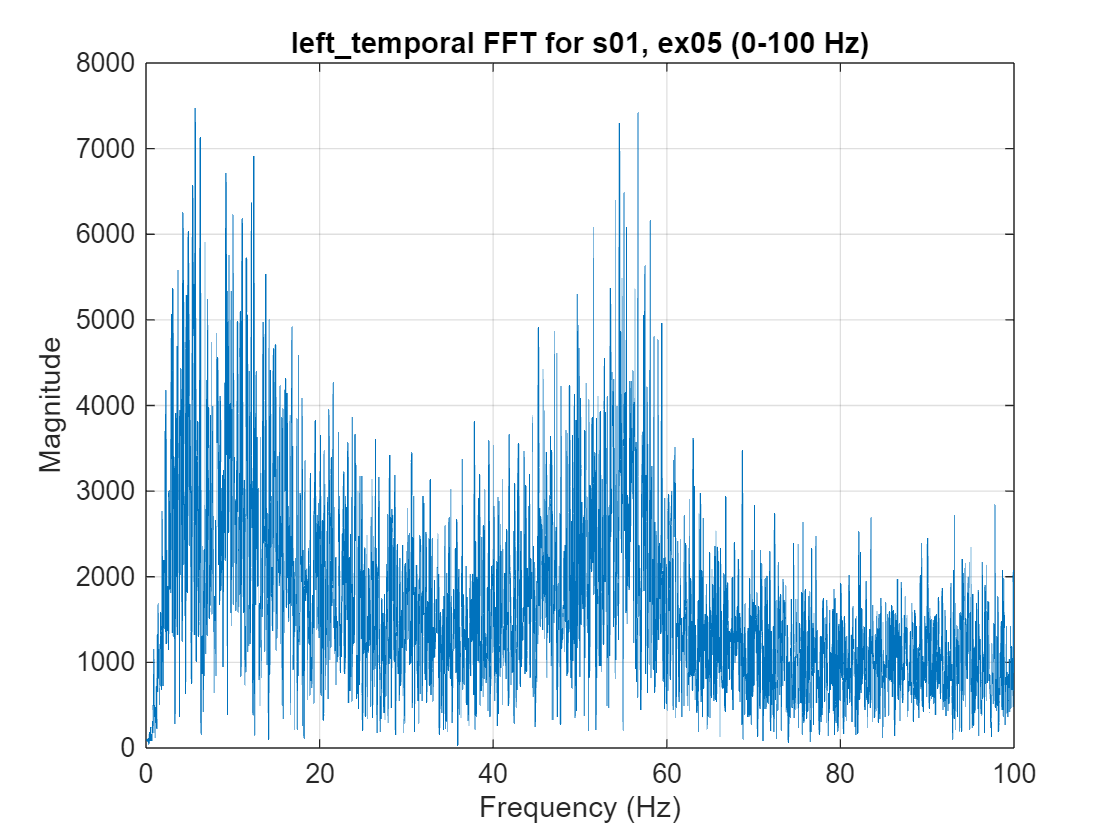

subject = 's01';  
experiment = 'ex05';
fftData = EEG_Analyzed_Data.(subject).(experiment);


N = length(fftData.right_parietal); 
f = (0:N-1)*(Fs/(2*N));

fields = fieldnames(fftData);


for i = 1:numel(fields)
    
    Y = fftData.(fields{i});
    
    
    figure;
    plot(f, Y);
    title([fields{i}, ' FFT for ', subject, ', ', experiment, ' (0-100 Hz)'], 'Interpreter', 'none');
    xlabel('Frequency (Hz)');
    xlim([0,100])
    ylabel('Magnitude');
    grid on;
end

Plotting accross experiments for one subject and one electrode

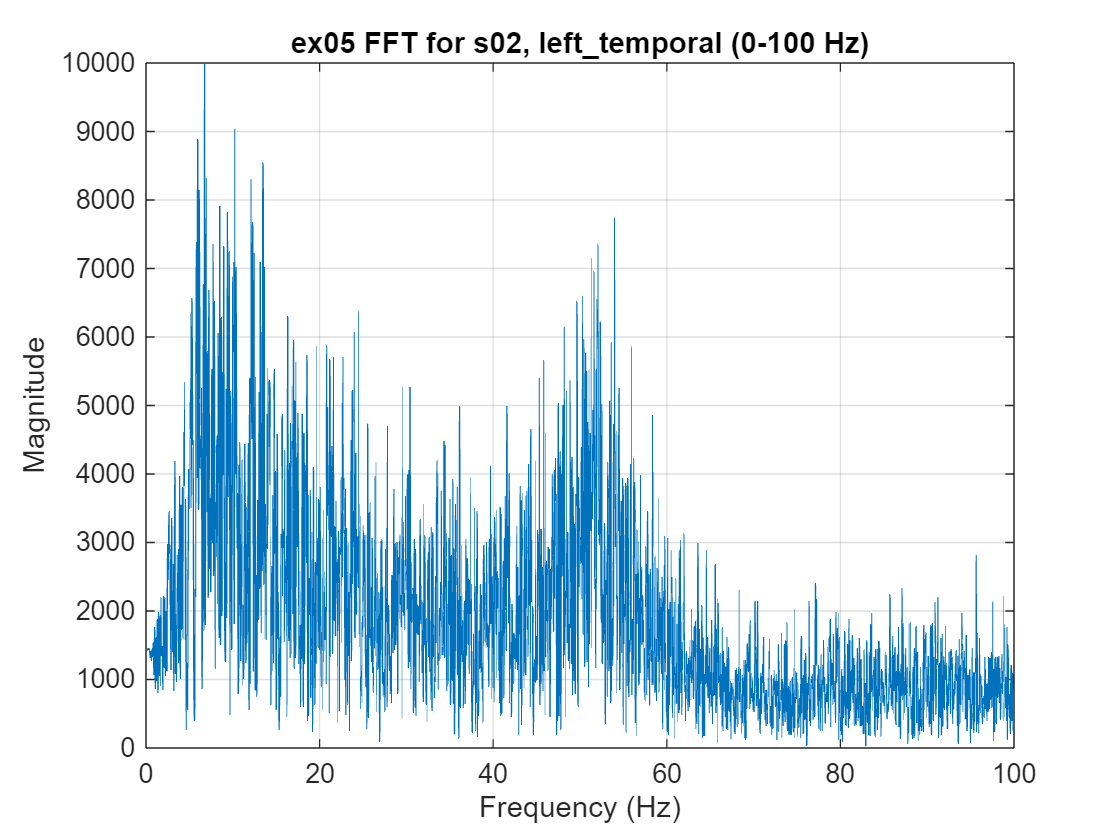

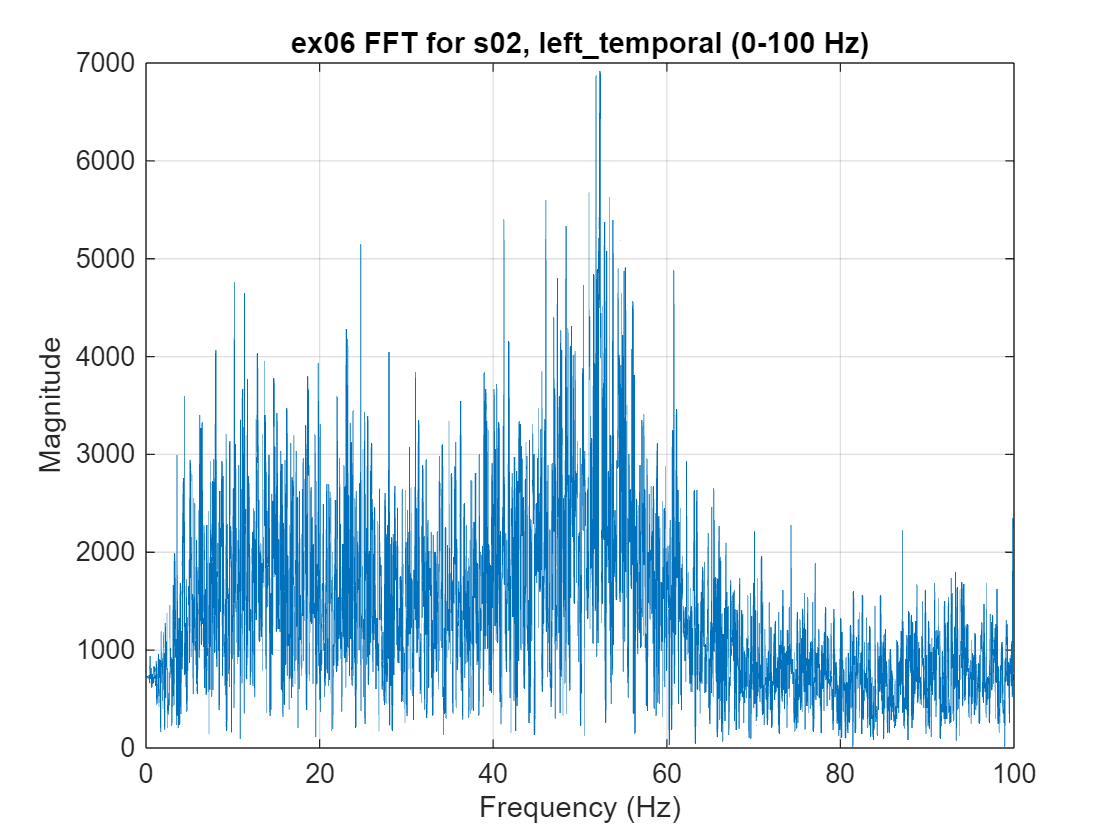

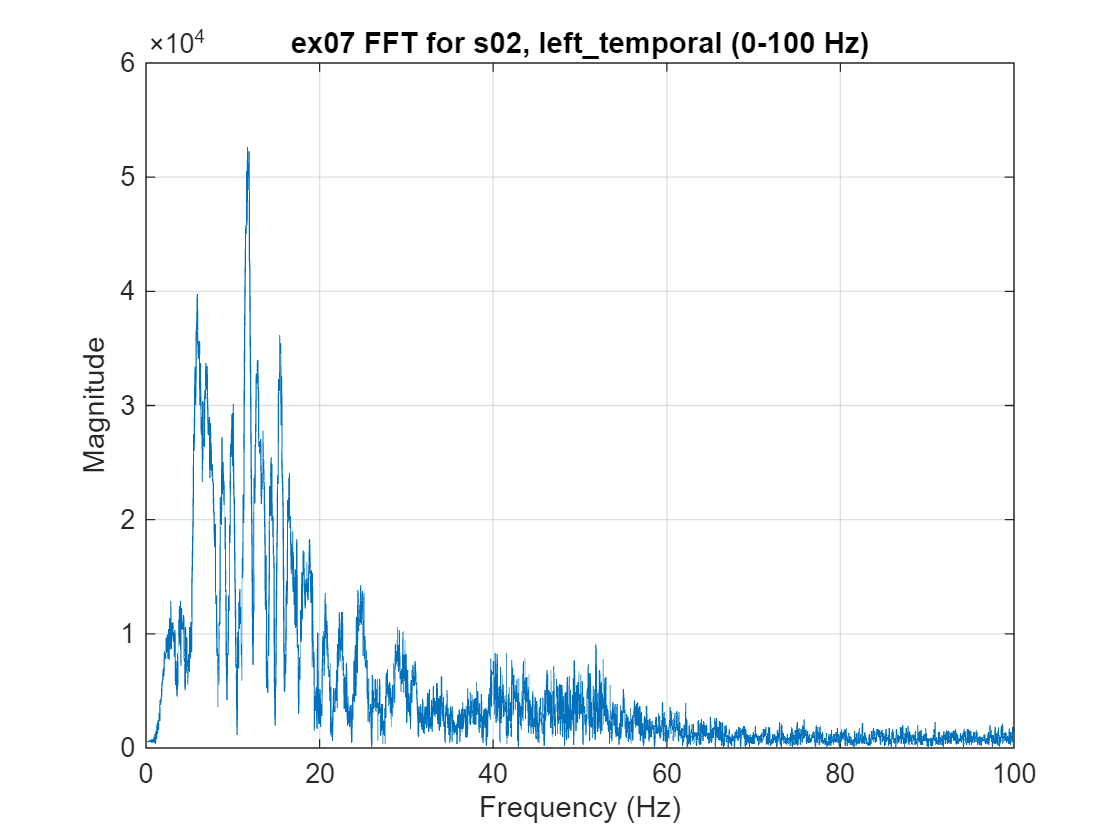

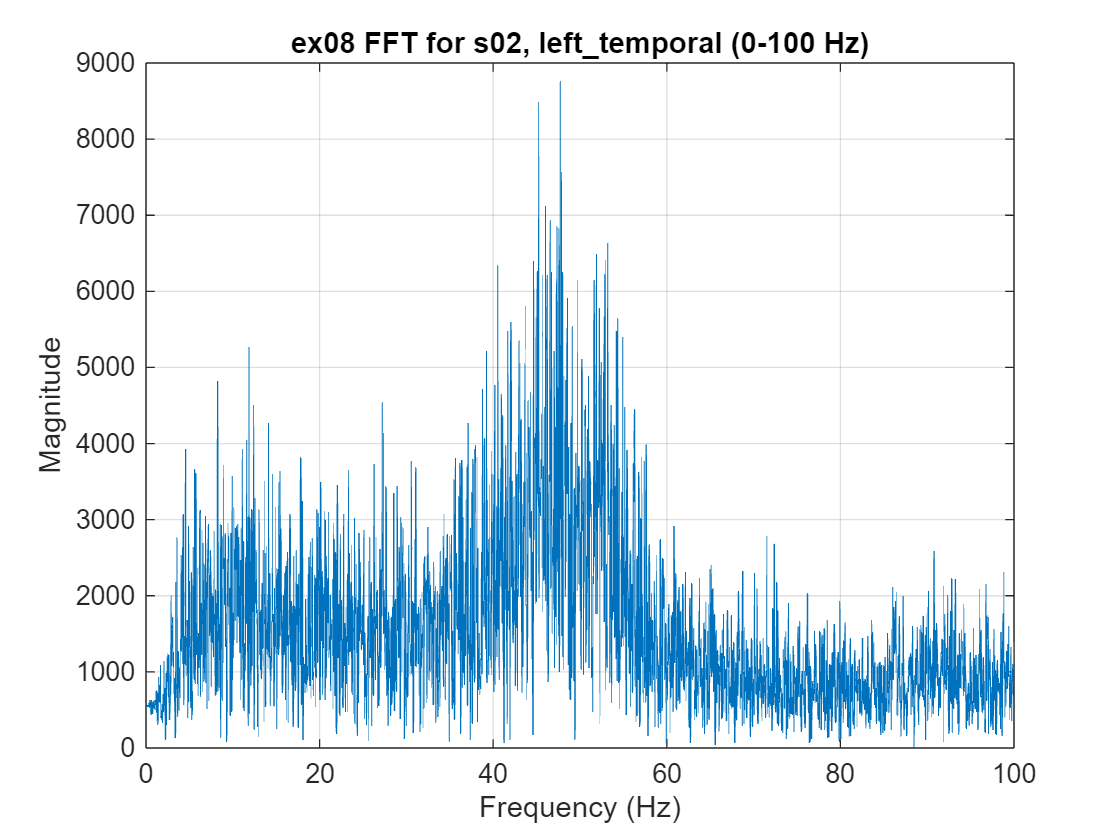

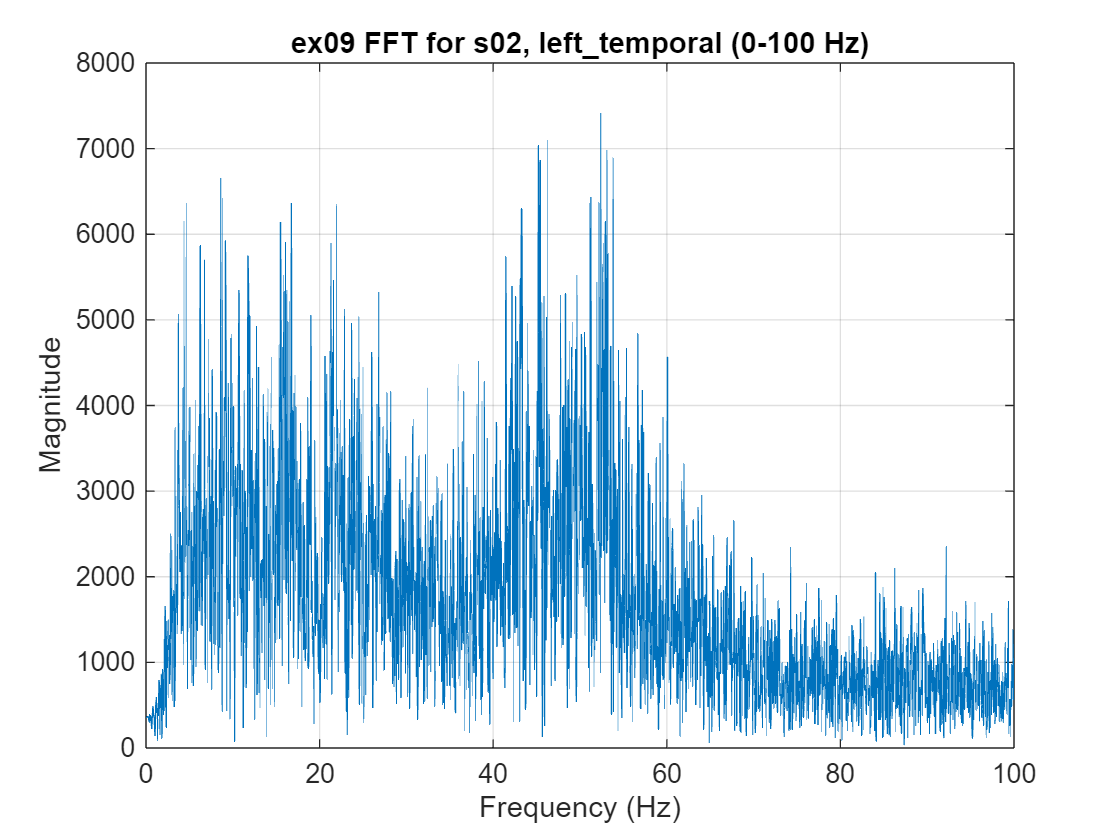

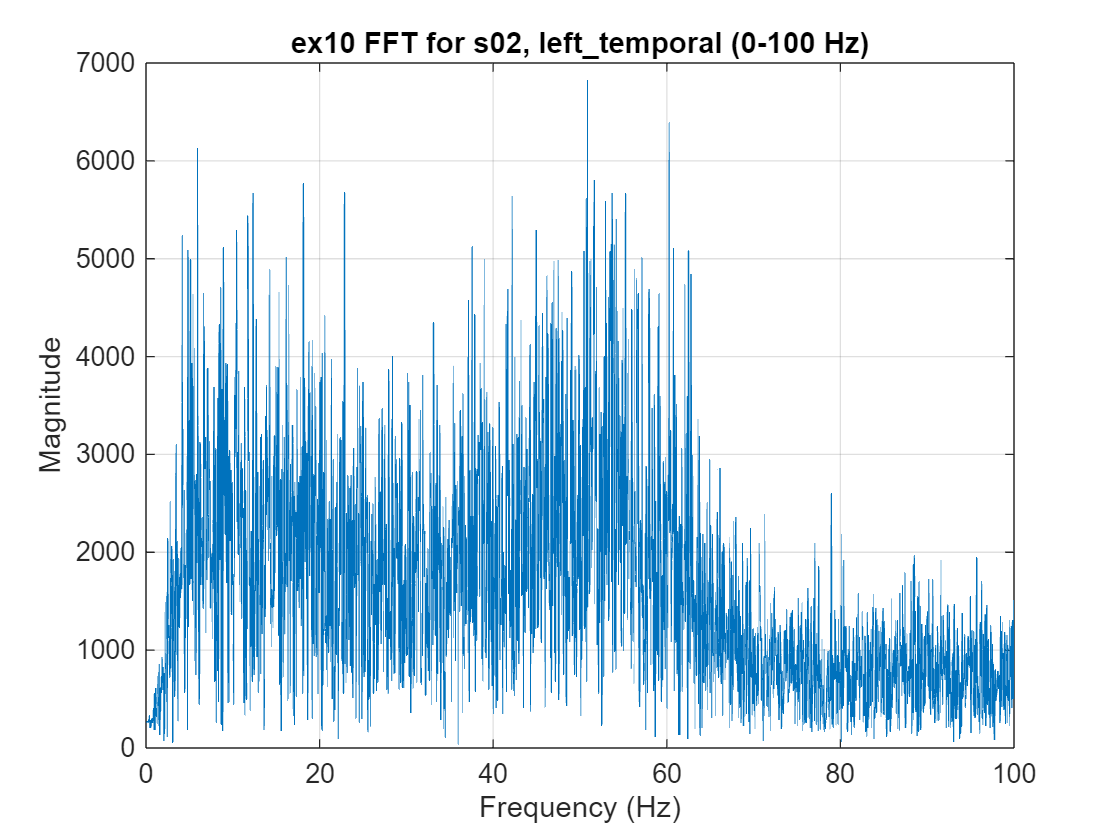

subject = 's02';  
electrode = 'left_temporal';
fftData = EEG_Analyzed_Data.(subject).(experiment);


experiments = fieldnames(EEG_Analyzed_Data.(subject));

for i = 1:numel(experiments)
    
    experiment = experiments{i};
    Y = EEG_Analyzed_Data.(subject).(experiment).(electrode);

    N = length(Y); 
    f = (0:N-1)*(Fs/(2*N));
    
    figure;
    plot(f, Y);
    title([experiment, ' FFT for ', subject, ', ', electrode, ' (0-100 Hz)'], 'Interpreter', 'none');
    xlabel('Frequency (Hz)');
    xlim([0,100])
    ylabel('Magnitude');
    grid on;
end